# Transfer Learning with MATLAB®

In this exercise, you will use transfer learning to classify images into 1 of 5 different food categories:

- Pizza

- Hot Dog

- Sushi

- French Fries

- Hamburger

## Are You in the Correct Directory?

% Run this to check
if isfolder('04-AdditionalFiles')
    disp('You are in the correct directory. Please continue.')
    addpath(genpath(pwd))
else  
    disp('Please navigate to the proper Directory')
end

## Create a Datastore

We used a datastore previously to read images in a loop. With [`ImageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) you can also label images, set a custom read function and split images into different sets. 

Create a datastore, including subdirectories and add labels based on the filenames.

filePath = fullfile('04-Images');

imds = imageDatastore(filePath,...  
    'IncludeSubfolders',true,...
    'LabelSource','foldernames'); 

## Look at Images from Dataset

Let's get a feel for the dataset. 

% Generate random number < # of total images
randNum = randi(length(imds.Files));
% Read random image from the datastore and visualize
[imTemp,info] = readimage(imds,randNum);
imshow(imTemp)
title(char(info.Label),'Interpreter','none')

## Splitting Image datastore into 3 sets:  | Train | Validation | Test |

It is a best practice to split our data into a training, validation and test set.

- Training - used to train our network by establishing proper weights that allow for accurate classification

- Validation - a dataset that you test the network on while training. If the results are poor, retrain the network with different hyperparameters and/or network architecture

- Test - an unseen dataset that is used as an unbiased measurement of network accuracy. Use this after you are happy with your validation performance.

There is not a perfect way to split your data, but people often do a 70/15/15 split. Use the [splitEachLabel](https://www.mathworks.com/help/matlab/ref/datastore.spliteachlabel.html) function to split your datastore into the three desired sets.

[trainDS, valDS, testDS] = splitEachLabel(imds,0.7,0.15,0.15,'randomized');

## Deep Network Designer

We will perform the entire [transfer learning](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html) workflow in the deep network designer (DND) app.

If you** cannot open DND**, open the script below

edit TransferLearningWithoutDND.mlx

#### Step 1: Import GoogLeNet

In transfer learning the majority of the layers stay the same. We need to modify the last few layers to fit our specific dataset. 

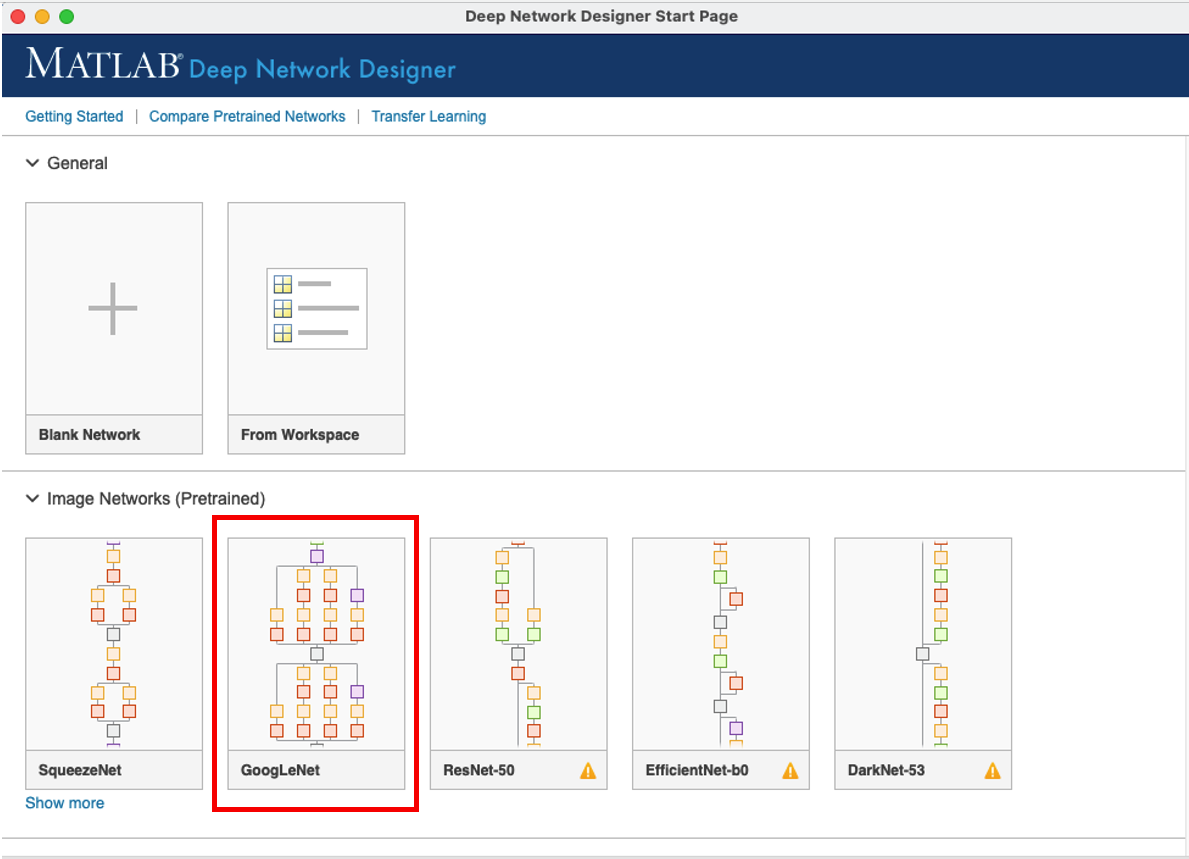

#### Step 2: Modify GoogLeNet

Instructions:

- Remove the last three layers in the network

- Add in a new Fully Connected Layer, Softmax Layer, and Classification Layer

- In the **fullyConnectedLayer**, change **OutputSize = 5**

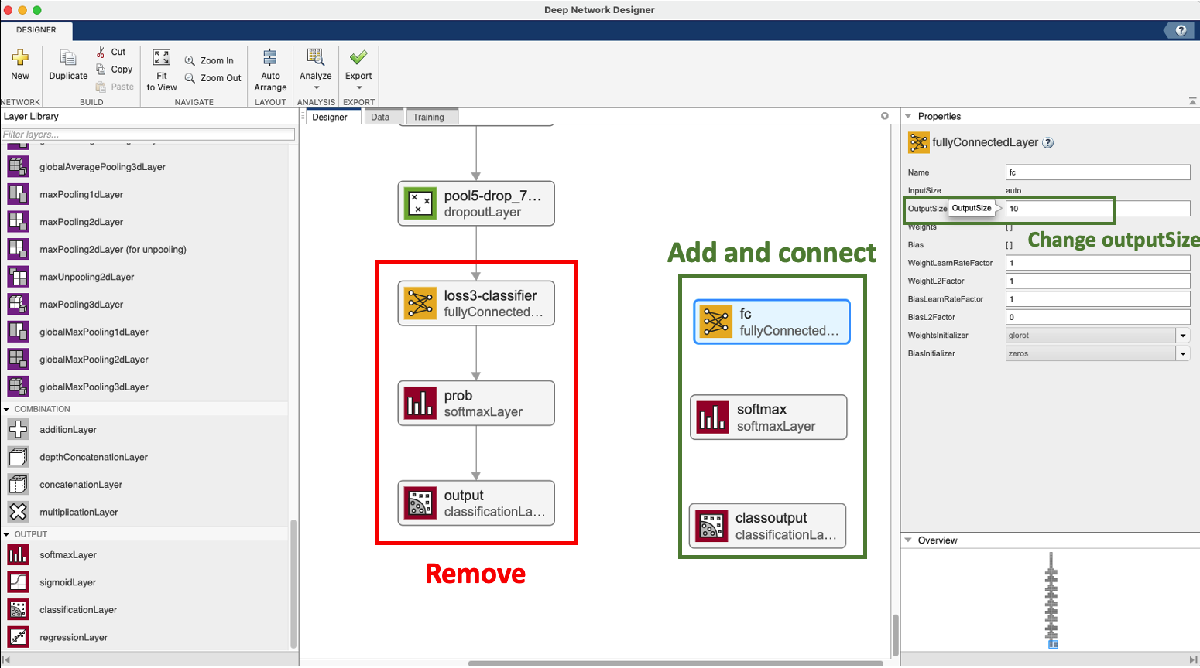

#### Step 3: Specify Data for Training and Validation

Navigate to the data tab and import the training and validation datastores.

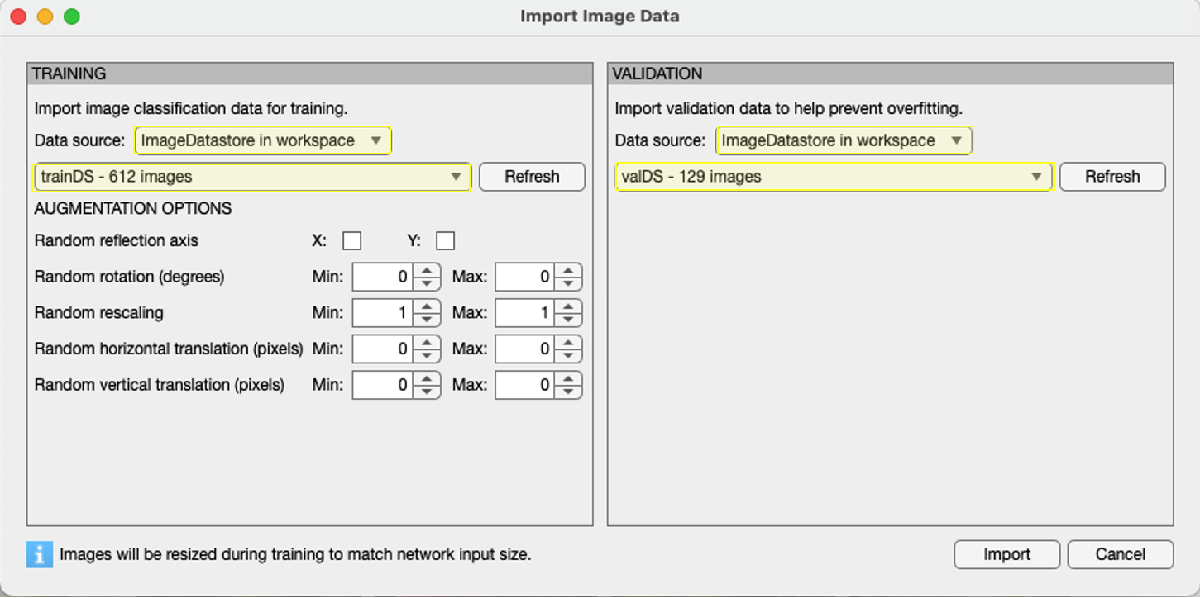

#### Step 4: Adjust Training Options

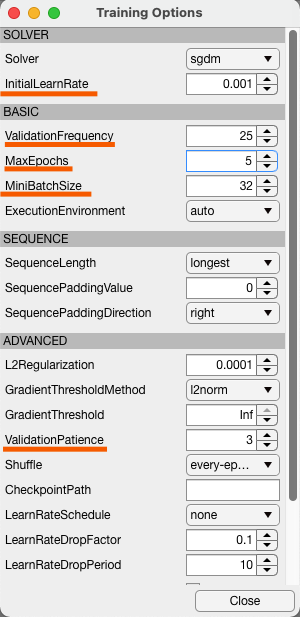

#### Step 5: Train the Network

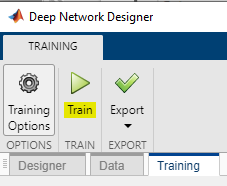

#### **Step 6: Export the Network and save results**

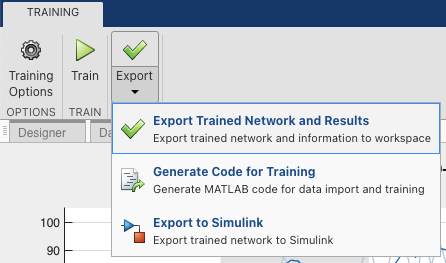

net_TransferLearning = trainedNetwork_1; clear trainedNetwork_1 trainInfoStruct_1
save('04-AdditionalFiles/net_TransferLearning.mat','net_TransferLearning')

## No GPU? Run This.

if ~exist('net_TransferLearning','var')
    disp('No trained network in workspace')
    disp('Load pretrained network')
    load('net_TransferLearning.mat')
end

## Test the Network

Once happy with validation results, test the network on the test dataset uisng the arguments below:

- `Argument_1 = Trained Network`

- `Argument_2 = Resized Test Datastore`

% Augmented datastore used to resize images for GoogLeNet size requirement
inputSize = net_TransferLearning.Layers(1).InputSize(1:2);
resizedTestDS = augmentedImageDatastore(inputSize, testDS);

% EDIT CODE BELOW
[labels, scores] = classify(Argument_1, Argument_2);

## Calculate Accuracy

Try to answer the following questions:

- Are there trends in misclassification?

- Where might these trends come from?

accuracy = sum(labels == testDS.Labels)/numel(labels)

% Confusion Matrix - visual inspection of accuracy and error
cm = confusionchart(labels, testDS.Labels);
cm.RowSummary = 'row-normalized';
cm.Title = 'Food Classification Confusion Matrix';

## View Some of the Results

Write a script that will let you view some of the images in the test dataset

randNum = randi(length(testDS.Files));

% [ADD CODE HERE] 


## Visualization

MATLAB lets you visualize weights in one of the network layers. We can see different convolution filters and activations. What do you notice?

*Change the name of the network to match the network in your workspace.*

im = imread('04-Images/pizza/crop_pizza1.jpg'); % feel free to choose any image
imshow(im)
imR = imresize(im,inputSize);

label = classify(net_TransferLearning,imR);
title(['Predicted: ' char(label) ],'Interpreter','none')

View the different weights of the filters used for convolution

weights = net_TransferLearning.Layers(2).Weights;
weights = mat2gray(weights);
montage(weights)
title('First convolutional layer weights')

View the activations in the first convolution layer

conv1Name = net_TransferLearning.Layers(2).Name;
act1 = activations(net_TransferLearning,imResized,conv1Name,'OutputAs','channels');
sz = size(act1);
act1 = reshape(act1,[sz(1) sz(2) 1 sz(3)]);
figure;montage(mat2gray(act1),'Size',[8 12])
title('Activations of First Convolutional Layer')

*Copyright 2022 The MathWorks, Inc.*